# 01C. Numerical methods

## Mingyang Lu

## 01/07/2024

## Babylonian method

See the definition of the babylonian function at the end.

% Babylonian method to compute square root of a
disp(babylonian(2, 1));

Number of iterations: 4
    1.4142



disp(babylonian(2, 100));

Number of iterations: 10
    1.4142



disp(babylonian(2, 200));

Number of iterations: 11
    1.4142



## Cubic spline interpolation[¶](http://localhost:8888/notebooks/01C.ipynb#Cubic-spline-interpolation)

Sample data

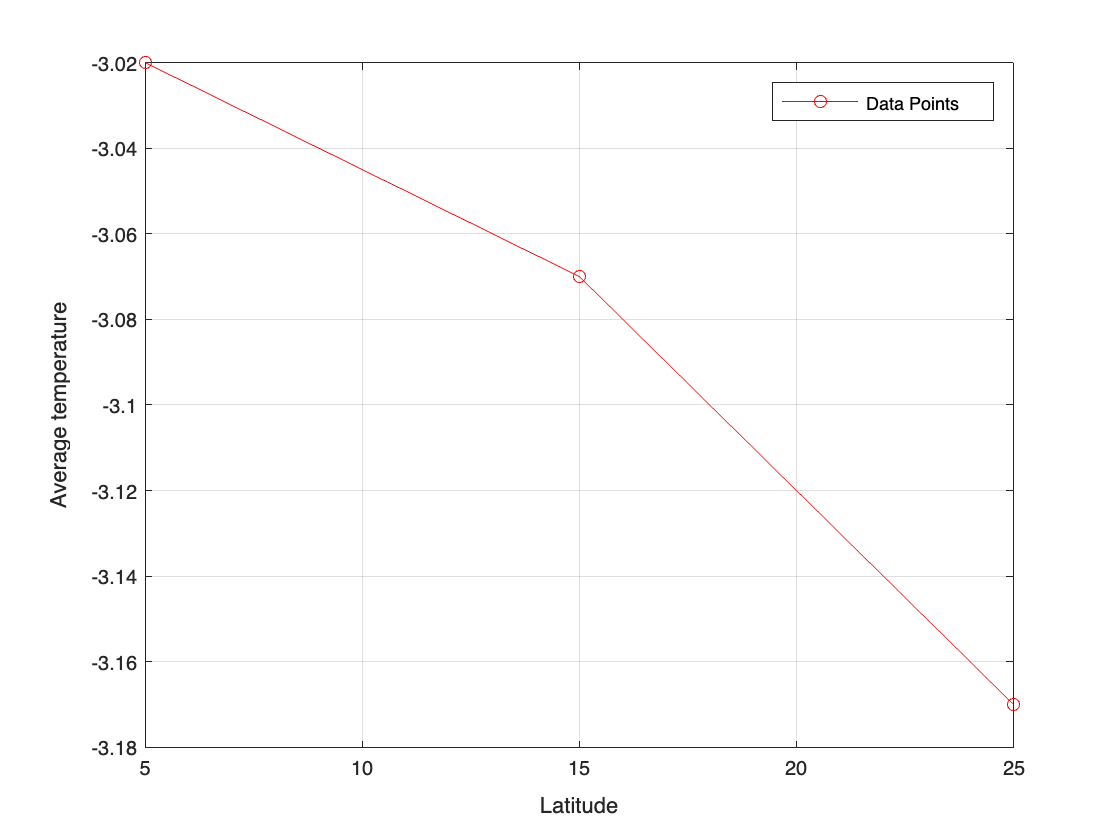

% Given data
x = [5, 15, 25];
y = [-3.02, -3.07, -3.17];

% Plotting
plot(x, y, 'ro-', 'LineWidth', 0.5, 'DisplayName', 'Data Points');
xlabel('Latitude');
ylabel('Average temperature');
legend('show');
grid on;

Example of cubic spline interpolation

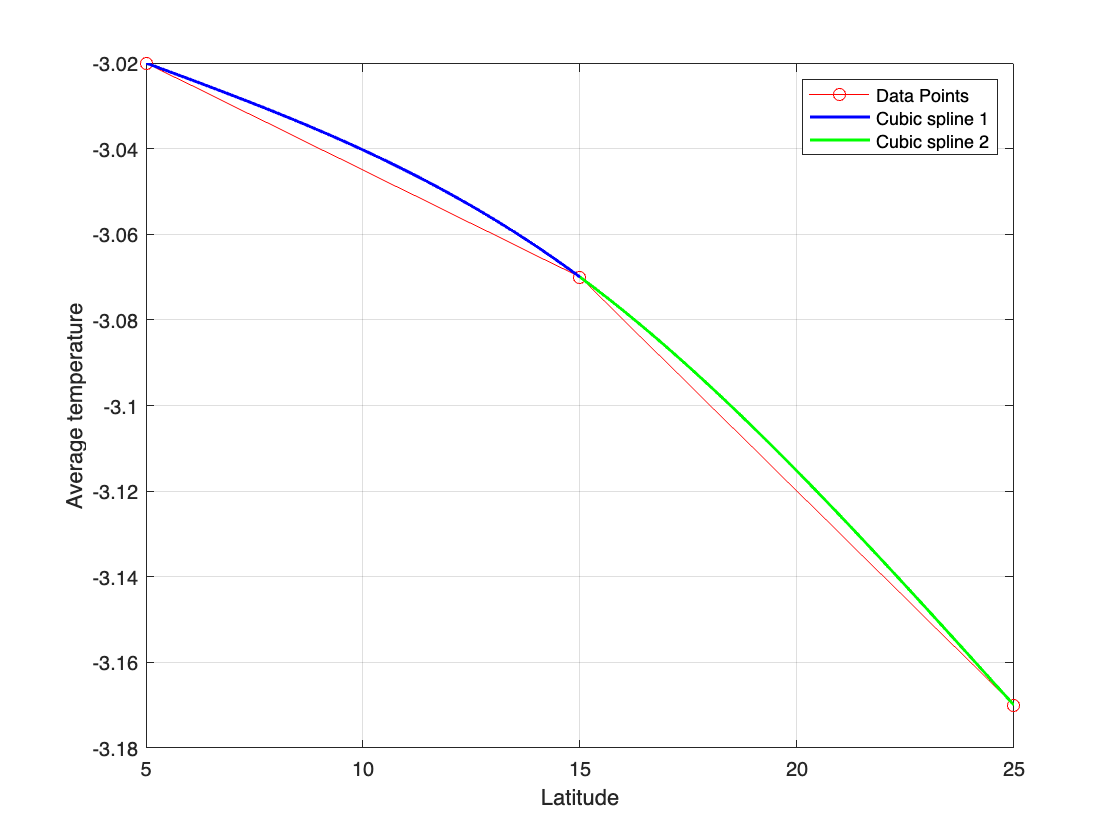

% Create the vector vec_c
vec_c = [y(1), y(2), y(2), y(3), 0, 0, 0, 0];

% Create the matrix a
a = [x(1)^3, x(1)^2, x(1), 1, 0, 0, 0, 0;
     x(2)^3, x(2)^2, x(2), 1, 0, 0, 0, 0;
     0, 0, 0, 0, x(2)^3, x(2)^2, x(2), 1;
     0, 0, 0, 0, x(3)^3, x(3)^2, x(3), 1;
     3*x(2)^2, 2*x(2), 1, 0, -3*x(2)^2, -2*x(2), -1, 0;
     6*x(2), 2, 0, 0, -6*x(2), -2, 0, 0;
     6*x(1), 2, 0, 0, 0, 0, 0, 0;
     0, 0, 0, 0, 6*x(3), 2, 0, 0];

% Solve for vec_p
vec_p = linsolve(a, vec_c.');

% Plotting
plot(x, y, 'ro-', 'LineWidth', 0.5, 'DisplayName', 'Data Points');
hold on;

x_vals_1 = linspace(x(1), x(2), 1000);
x_vals_2 = linspace(x(2), x(3), 1000);
plot(x_vals_1, vec_p(1) * x_vals_1.^3 + vec_p(2) * x_vals_1.^2 + ...
     vec_p(3) * x_vals_1 + vec_p(4), 'b-', 'LineWidth', 1.5, 'DisplayName', 'Cubic spline 1');
plot(x_vals_2, vec_p(5) * x_vals_2.^3 + vec_p(6) * x_vals_2.^2 + ...
     vec_p(7) * x_vals_2 + vec_p(8), 'g-', 'LineWidth', 1.5, 'DisplayName', 'Cubic spline 2');

xlabel('Latitude');
ylabel('Average temperature');
legend('show');
grid on;

### Define MATLAB functions

function result = babylonian(a, x1, epsilon)
    if nargin < 3
        epsilon = 1e-6;
    end

    if a <= 0 || x1 <= 0
        disp('a and x1 should be both positive!');
        result = 0;
        return;
    else
        x = x1;
        i = 0;
        while abs(x * x - a) > epsilon
            i = i + 1;
            x = (x + a / x) / 2;
        end
        fprintf('Number of iterations: %d\n', i);
        result = x;
    end
end